# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.1 曲线图、散点图

二维曲线、散点图算是最最常见的一种曲线了，直接反应两个变量的因果关系，散点图常用来比较理论数据和实验数据的趋势关系；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

设置线型（点线、虚线、实线、点虚线）、数据点标记（星号、圆、正方形等等）、线颜色、标记点颜色等等，使图形看起来更加优雅美观；

颜色设置格式：缩写字符（‘r’，固定颜色，种类较少）；

                         十六进制字符串（'#FD6D5A'，种类不限，每种颜色都需要逐个设置）；

                          RGB向量（[0.5, 0.5, 0.5]，种类不限，可设置颜色模板，使用最方便）；

clear;clc;close all;
%%%%% 曲线图
x = 0:0.4:2*pi;
y = sin(x);
% 在一个 figure 中绘制多个子图，(2, 1, 1) 表示 2 行 1 列第 1 个子图
figure;
subplot(2, 1, 1)   
% 绘制一条曲线
plot(x, y, '-d', 'Color', 'r', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'y',...
     'MarkerSize', 10, 'LineWidth', 2);
% d：表示倒置的菱形，-d表示用实线连接，r表示曲线红色，
% MarkerEdgeColor表示标记点轮廓颜色
%bMarkerFaceColor 表示标记点内部颜色
% MarkerSize 表示标记大小
% 各种线型、符号、颜色代码参考帮助，如下

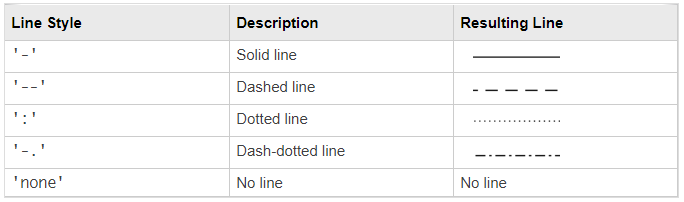

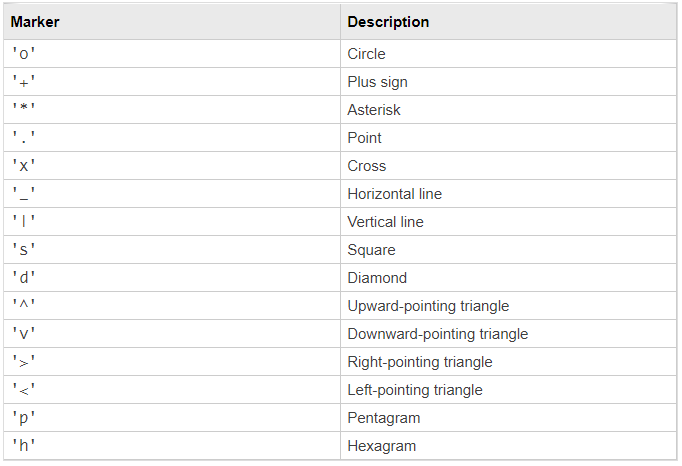

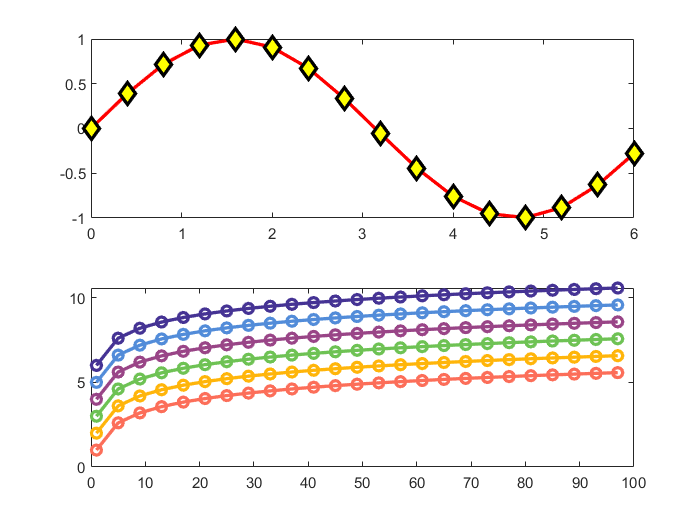

% 第二幅子图 
subplot(2, 1, 2)
% 绘制多条曲线
x = 1:4:100;
y = log(x);
for i = 1:6
    plot(x, y + i, 'o-', 'LineWidth', 2);
    hold on
end
hold off
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 修改默认的颜色模板
set(gca, 'colororder', all_themes{1});

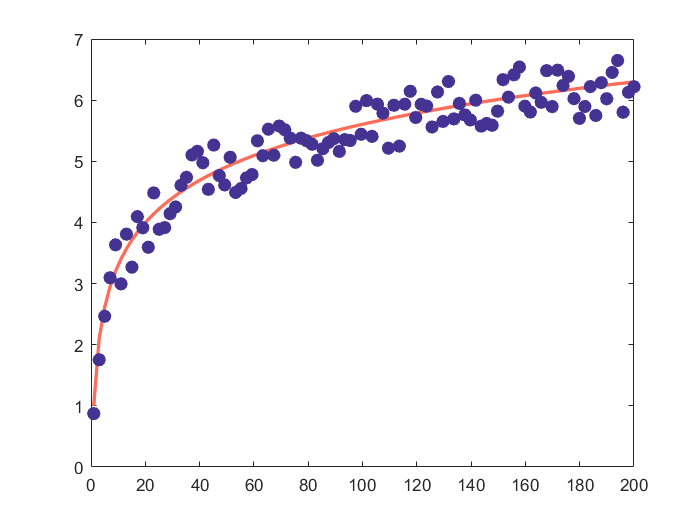

%%%%% 散点图
figure;
x = linspace(1, 200, 100);
y1 = log(x) + 1;
y2 = y1 + rand(1, 100) - 0.5;
plot(x, y1, 'LineWidth', 2, 'Color', all_colors(1, :));
hold on
% 设置数据点的形状、数据点的填充颜色、数据点的轮廓颜色
plot(x, y2, 'o', 'LineWidth', 2, 'Color', all_colors(6, :), 'MarkerFaceColor', all_colors(6, :));
hold off